clc
clear all
close all

## Define Space

F2N = dec2bin(2^8-1:-1:0)-'0';
F2N = F2N';

## Define the Canonical Parity Check Matrix

H = [1,0,0,0,1,1,1,0;0,1,1,0,0,1,1,0;1,0,1,0,0,1,1,1;1,0,1,1,0,1,0,0];
[m,n] = size(H);
H1 = H(1:m,1:n/2);
H2 = H(1:m,(n/2)+1:n);
Ha = abs(rref(H));

## Define the Generator Matrix

A = Ha(1:m,(n/2)+1:n);
I = Ha(1:m,1:n/2);
G = [A;I];
[p,q] = size(G);
Pm = 0.49; %Probability of Getting 1 in message word
Pe = 0.49; %Probability of Getting 1 in error word
t = 1000;

x = 4×1 logical array
   1
   0
   0
   0


e = 8×1 logical array
   0
   1
   1
   1
   1
   1
   1
   0


## Results

**Calculating the Error Rate for a particular p**

[y,x] = CodeWordVector(G, q, Pm);
MessageVector = x

MessageVector = 4×1 logical array
   0
   0
   0
   1


Error = MLAlgo(t,F2N',y,H,Pe,n)

Error = 0.9400

**Varying p and plotting the Error rate versus crossover probability p**

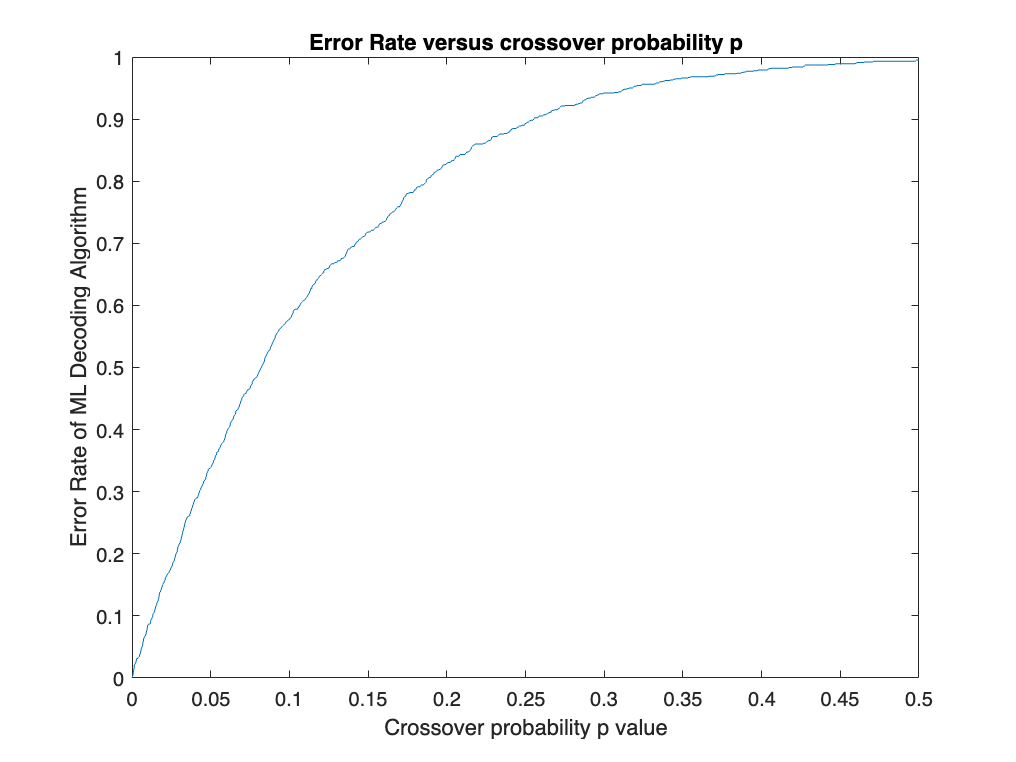

PlottingErrorRate(t,F2N',y,H,n)

## **Plotting Function for Error-Rate**

function PlottingErrorRate(t,funcspace,y,H,n)
    p = linspace(0,0.5,1000);
    ErrorRate = MLAlgo(t,funcspace,y,H,p,n);
    figure;
    plot(p,ErrorRate);
    
    title('Error Rate versus crossover probability p');
    xlabel('Crossover probability p value');
    ylabel('Error Rate of ML Decoding Algorithm');
end

## Maximum Likelihood Decoding Algorithm

function ErrorRate = MLAlgo(t,funcspace,y,H,Pe,n)
    total_error = 0;
    for i = 1:t
        [Y,e] = CorruptCodeWordVector(y,n,Pe);
        s = FilteredCCW(H,Y);
        total_error = total_error + ComputingMLDecodingError(funcspace,H,s,e);
    end
    ErrorRate =  total_error/t;
end

## Computing Maximum Likelihood Decoding Error

function error = ComputingMLDecodingError(funcspace,H,s,e)
e_hat = 0;
currentHammingCode = -1;
    for i = 1:length(funcspace)
        if s == mod(H*funcspace(i,:)',2)
            if currentHammingCode == -1 || currentHammingCode > sum(funcspace(i,:))
                e_hat = funcspace(i,:)';
                currentHammingCode = sum(e_hat);
            end
        end
    end
    error  = sum(mod(e_hat-e,2)) > 0;
end

## Filtering of the Corrupt Code Word Vector

function s = FilteredCCW(H,Y)
s = mod(H*Y,2);
end

## Generation of Corrupt Code Word Vector

function [Y,e] = CorruptCodeWordVector(y,n,Pe)
e = RandomErrorVector(n, Pe);
Y = mod(y+e,2);
end

## Generation of Code Word Vector

function [y,x] = CodeWordVector(G, q, Pm)
x = RandomMessageVector(q, Pm);
y = mod(G*x,2);
end

## Generation of Random Message Vector

function x = RandomMessageVector(q, Pm)
x = rand(q,1)<Pm;
end

## Generation of Error Vector

function e = RandomErrorVector(n, Pe)
e = rand(n,1)<Pe;
end